# Prediction With Pretrained Model

This demo import pretrained RNN model that trained based on DNS challenge clean and noise data. It allow user to upload a local speech audio and combine with a random noise result. Then model predict based on provided input and will display graph of denoised audio. 

clear all
close all
clc

## Load the pretrained network

load('DenoiseNet0420.mat');

## Choose the speech

[file,path] = uigetfile('./Databases/*.wav', 'Select the speech files', 'MultiSelect', 'on'); 
[audio_test,fs_test] = audioread([path,file]);

% Import noise dataset
noiseFolder = "../datasets_fullband/noise_fullband";
adsNoise = audioDatastore(fullfile(noiseFolder));
noise_test = read(adsNoise);

% Set the audio samples to uniform length of 10 seconds
inputFs = 48000;
expected_length = 10;
if length(audio_test) > expected_length * inputFs
    audio_test = audio_test(1:expected_length * inputFs);
else
    blankSignal = zeros(expected_length * inputFs - length(audio_test),1);
    audio_test = [audio_test; blankSignal];
end

if length(noise_test) > expected_length * inputFs
    noise_test = noise_test(1:expected_length * inputFs);
else
    blankSignal = zeros(expected_length * inputFs - length(noise_test),1);
    noise_test = [noise_test; blankSignal];
end

## Sample rate reset

Convert audio to uniform sample rate and set signal-to-noise ratio (SNR) to zero dB.

decimationFactor = 6;
src = dsp.SampleRateConverter("InputSampleRate",fs_test, ...
                              "OutputSampleRate",fs_test/decimationFactor, ...
                              "Bandwidth",7920);
fs_test=fs_test/decimationFactor;
L = floor(numel(audio_test)/decimationFactor);
audio_test = audio_test(1:decimationFactor*L);
audio_test = src(audio_test);
reset(src);
noise_test = noise_test(1:decimationFactor*L);
reset(src);
noise_test = src(noise_test);

% Set the noise power such that the signal-to-noise ratio (SNR) is zero dB
speechPower = sum(audio_test.^2);
noisePower = sum(noise_test.^2);
noisyAudioTest = audio_test + sqrt(speechPower/noisePower) * noise_test;

Visualize original and randomly selected noise signal.

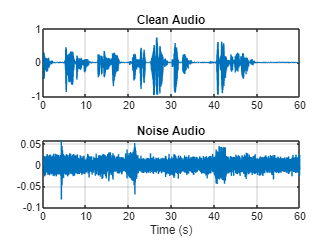

t = (1/(fs_test/decimationFactor))*(0:numel(audio_test) - 1);
figure(1)
tiledlayout(2,1)

nexttile
plot(t,audio_test)
title("Clean Audio")
grid on

nexttile
plot(t,noise_test)
title("Noise Audio")
xlabel("Time (s)")
grid on

## Preprocess noisy audio

frameLength=0.02; %s
frameOverlap=0.01; %s
windowLength=frameLength*fs_test;
windowOverlap=frameOverlap*fs_test;
N=windowLength;
m=0:N-1;
K=1;
giveMFCCnums=8;
sineWindow=sin((pi * K * (m+1))/(N+1));

i=1;
number_MFCCs=16;
for k=1:number_MFCCs %DCT
    n=0:2*number_MFCCs-1;
    dctcoef(k,:)=cos((2*n+1)*k*pi/(2*2*number_MFCCs));
end
bank=melbankm(2*number_MFCCs,windowLength,fs_test,0,0.5,'t');
%mel filter bank
bank=full(bank);
bank=bank/max(bank(:));
tic;
i=1;
MFCC_noisy_test=zeros(round((size(noisyAudioTest,1)-windowLength)/windowOverlap),number_MFCCs+giveMFCCnums);
noisyFrameTest=zeros(round((size(noisyAudioTest,1)-windowLength)/windowOverlap),windowLength);
while windowLength+(i-1)*windowOverlap<size(noisyAudioTest,1)
    noisyFrameTest(i,:)=noisyAudioTest((i-1)*windowOverlap+1:(i-1)*windowOverlap+windowLength);
    noisyFrameTest(i,:)=noisyFrameTest(i,:).*sineWindow;
    s=noisyFrameTest(i,:);
    t=abs(fft(s));
    t=t.^2; 
    c=dctcoef*log(bank*t(1:windowLength/2+1)'); 
    MFCC_noisy_test(i,1:number_MFCCs)=c'; 
    if giveMFCCnums > 0
        MFCC_noisy_test(i,number_MFCCs+1:number_MFCCs+giveMFCCnums)=getMFCCdet(c',giveMFCCnums);
    end
    i=i+1;
end

## Make prediction

pres=predict(net, MFCC_noisy_test);
g_b=pres;
w_b=get_wb();
r_k=ones(size(g_b,1),windowLength);
for i=1:size(g_b,1)
    temp_gb=g_b(i,:)';
    temp_gba=repmat(temp_gb,1,windowLength);
    gb_wb=temp_gba.*w_b;
    r_k(i,:)=sum(gb_wb);
end
recAudio=zeros(1,108000);
for numberFrame=1:size(noisyFrameTest,1)
    tempNoisyFrame=noisyFrameTest(numberFrame,:);
    tempNoisyFrame=tempNoisyFrame.*sineWindow;
    tempNoisyFrame_f=fft(tempNoisyFrame);
    recNoisyTest=ifft(tempNoisyFrame_f.*r_k(numberFrame,:));
%     recNoisyTest=ifft(tempNoisyFrame_f);
    if numberFrame==1
        recAudioTest(1:N)=recNoisyTest;
    else
        recAudioTest((numberFrame-1)*windowOverlap+1:(numberFrame-2)*windowOverlap+windowLength)...
            =recAudioTest((numberFrame-1)*windowOverlap+1:(numberFrame-2)*windowOverlap+windowLength)+recNoisyTest(1:N/2);
        recAudioTest((numberFrame-2)*windowOverlap+windowLength+1:(numberFrame-1)*windowOverlap+windowLength)=recNoisyTest(N/2+1:N);
    end
    % subplot(4,1,3)
    % plot(tempAudioFrame)
    % subplot(4,1,4)
    % plot(recNoisy)
end
toc;

Elapsed time is 2.009641 seconds.


## Play processed audio

recAudios=real(recAudioTest);
snr1=calcu_snr(audio_test(1:size(recAudios,2)),noisyAudioTest(1:size(recAudios,2)));
snr=calcu_snr(audio_test(1:size(recAudios,2)),recAudios');
% sound(audio_test)
% sound(noisyAudioTest)
audio_test=audio_test(1:size(recAudios,2));
noisyAudioTest=noisyAudioTest(1:size(recAudios,2));
recAudios=recAudios';
% sound(recAudios)
sound(recAudios/abs(max(recAudios)))

## Draw denoised vs. original

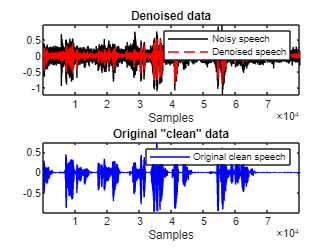

figure(1); clf;
set(gcf, 'name', 'Audio waveform comparison');
subplot(2,1,1)
plot(noisyAudioTest,'k')
title('Denoised data');
hold on
plot(recAudios,'r--')
legend('Noisy speech','Denoised speech')
axis tight
xlabel('Samples')
subplot(2,1,2);
plot(audio_test,'b')
title('Original "clean" data')
legend('Original clean speech')
axis tight
xlabel('Samples')

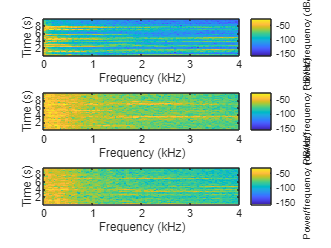



figure(2); clf;
subplot(3,1,1)
spectrogram(audio_test,256,250,256,8e3);
subplot(3,1,2)
spectrogram(noisyAudioTest,256,250,256,8e3);
subplot(3,1,3)
spectrogram(recAudios,256,250,256,8e3);


% wavwrite(noisyAudioTest,8000,'noisy_f5.wav')
% % wavwrite(audio_test,8000,'clean.wav')
% wavwrite(recAudios/abs(max(recAudios)),8000,'rec_f5.wav')